clc
close all
clear all
cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/';
currentfolder = 'toy_exp_50_0.5/'

currentfolder = 'toy_exp_50_0.5/'

index = 0

index = 0

index_s = int2str(index)

index_s = '0'

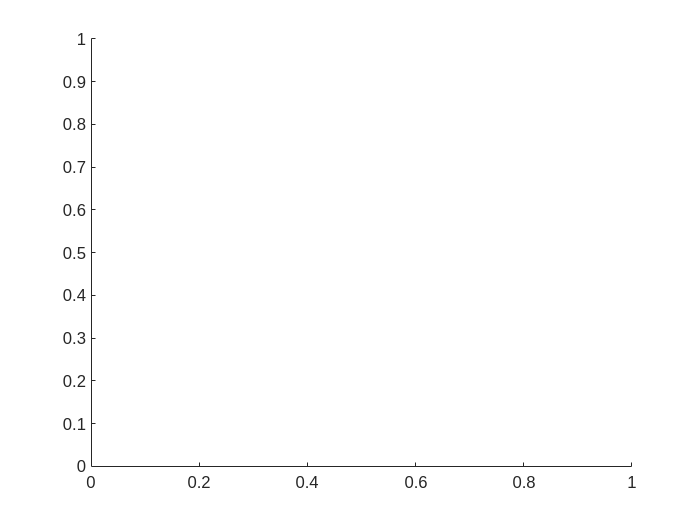

V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';
V = {V1,V2,V3,V4}';
figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

figure(2) 
hold on

for i=1:4
    pointscolor=uint8(zeros(V{i}.Count,3));
    pointscolor(:,1)=colormap{i}(1);
    pointscolor(:,2)=colormap{i}(2);
    pointscolor(:,3)=colormap{i}(3);
    V{i}.Color=pointscolor;
   
    pcshow(V{i},'MarkerSize', 70,'MarkerFaceAlpha', 0.5);
    set(gcf, 'color','w')
    
    
    view([70.588 -11.986])
end

Error using pcshow
'MarkerFaceAlpha' is not a recognized parameter. For a list of valid name-value pair arguments, see the documentation for pcshow.

Error in pcshow>validateAndParseInputs (line 82)
parser.parse(pvpairs{:});

Error in pcshow (line 6)
[X, Y, Z, C, map, ptCloud, params] = validateAndParseInputs(varargin{:})

hold off


## color ICP result

% cla
% gtfilename = append(rootfolder,currentfolder,index_s,'/color_icp.txt')
% A = readmatrix(gtfilename);
% Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% figure(3)
% hold on
% for i=1:4
%     T = Tcvo{i};
%     transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
%     ptCloudOut = V{i};
%     ptCloudOut = pointCloud(transform_p);
%     ptCloudOut.Color = V{i}.Color;
%     pcshow(ptCloudOut);
%     view([1.8 24.5])
%     set(gcf, 'color','w')
% end
% hold off

## Read cvo pose and do transformation

cla
gtfilename = append(rootfolder,currentfolder,index_s,'/rkhs_results.txt')
A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
figure(3)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = V{i}.Color;
    pcshow(ptCloudOut,'MarkerSize', 70);
    xlim([-0.264 0.215])
    ylim([-0.144 0.316])
    zlim([-0.187 0.263])
    view([-8.744 90.000])
    set(gcf, 'color','w')
end
hold off



## Read jrmpc pose and do transformation

cla
gtfilename = append(rootfolder,currentfolder,index_s,['/jrmpc.txt'])
A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
figure(3)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = V{i}.Color;
    pcshow(ptCloudOut,'MarkerSize', 70);
    xlim([-0.264 0.215])
    ylim([-0.144 0.316])
    zlim([-0.187 0.263])
    view([-3 90.000])
    set(gcf, 'color','w')
end
hold off

## Original bunny


cla
rootfolder = '../../exp/';
currentfolder = 'toy_exp_12.5_0.0/'
index = 0
index_s = int2str(index)
V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';
V = {V1,V2,V3,V4}';
figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};


gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')
A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
for i=1:4
    Tcvo{i} = inv(Tcvo{i});
end
figure(7)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    pointscolor=uint8(zeros(V{i}.Count,3));
    pointscolor(:,1)=colormap{i}(1);
    pointscolor(:,2)=colormap{i}(2);
    pointscolor(:,3)=colormap{i}(3);
   
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = pointscolor;
    pcshow(ptCloudOut,'MarkerSize', 70);
    xlim([-0.264 0.215])
    ylim([-0.144 0.316])
    zlim([-0.187 0.263])
    view([-8.744 90.000])
    set(gcf, 'color','w')
end
hold off
